## Bivariate Normal PDF properties

A bivariate Normal probability density function (pdf) has the form

$p_{XY}(x,y;\overline{\mu},{\bf C}) = \frac{1}{2\pi |{\bf C}|^{1/2}} \exp\left(-\frac{1}{2}(\overline{x}-\overline{\mu}){\bf C}^{-1} (\overline{x}-\overline{\mu})^T\right)$, where

$\overline{x} = (x,y)$, $\overline{\mu} = (\mu_x, \mu_y)$, ${\bf C}$ is the covariance matrix, and $|{\bf C}|$ is its determinant. We can further write,

${\bf C} = \left(\begin{array}{cc} \sigma_X^2 & \rho \sigma_X \sigma_Y\\ \rho \sigma_X \sigma_Y & \sigma_Y^2 \end{array}\right)$,

where $\rho$ is the **correlation coefficient**. It determines how much the trial values of one variable depend on those of the other. When $\rho = 0$, we say the random variables are **uncorrelated**. For the bivariate Normal, zero correlation also means statistical independence. However, this need not be true in general.

We can make contour plots of the bivariate Normal pdf.

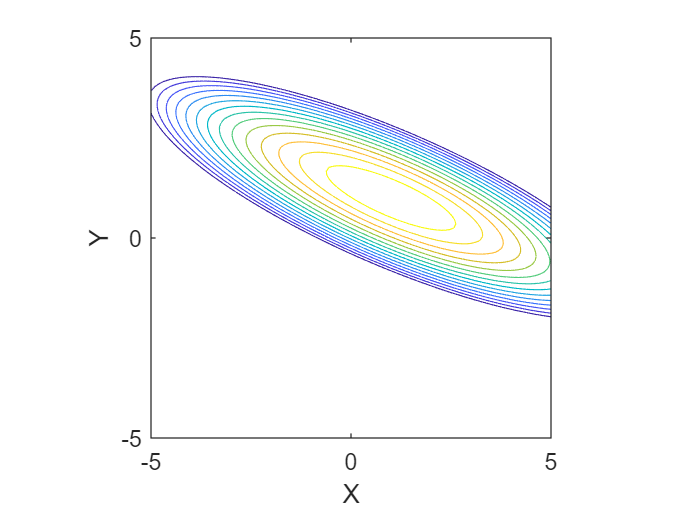

%Parameters of the bivariate normal pdf
muVec = [1,1]; %mean vector
stdevX = 2.0; %standard deviation of X
stdevY = 1.0; %standard deviation of Y
rho = -0.8; %correlation coefficient
plotbivarcontours(rho, stdevX, stdevY, muVec);

## Bivariate Normal pseudo-random numbers

We can draw trial values of bivariate Normal random variables. For this, we first draw trial values of uncorrelated Normal random variables and take their linear combinations. These linear combinations will be bivariate normal with a non-zero correlation. (Any linear combination of Normal random variables is also Normal.) We can prove this as shown below, where $X$ and $Y$ are independent Normal variables having $E[X]=E[Y]=0$, $\sigma_X^2=\sigma_Y^2 = \sigma^2 = E[X^2] = E[Y^2] = 1$, and $E[XY]=0$.

Linear combinations:$W = a_1 X + b_1 Y$, and $Z = a_2 X + b_2 Y$.


$$\sigma_W^2 = C_{WW} = E[(a_1 X+b_1 Y)^2] = E[a_1^2 X^2 + b_1^2 Y^2 + 2 a_1 b_1 XY] = a_1^2\sigma_X^2+b_1^2\sigma_Y^2 = a_1^2 + b_1^2$$



$$\sigma_Z^2 = a_2^2 + b_2^2$$



$$C_{XY}=E[(a_1 X + b_1 Y)(a_2 X +b_2 Y)] = E[a_1 a_2 X^2 + b_1 b_2 Y^2 + a_1 b_2 XY + b_1 a_2 YX] = \sigma^2 (a_1 a_2 + b_1 b_2)$$



$$\rho = \frac{C_{XY}}{\sigma_X \sigma_Y} = \frac{a_1a_2+b_1b_2}{\sqrt{a_1^2+b_1^2}\sqrt{a_2^2+b_2^2}}\leq 1$$


$\rho$ is simply the dot product of two unit vectors $(a_1, b_1)/\sqrt{a_1^2+b_1^2}$ and $(a_2, b_2)/\sqrt{a_2^2 + b_2^2}$. So, if we pick $\widehat{w}=(a_1, b_1)$ and $\widehat{z}=(a_2, b_2)$ to be unit vectors to start with, $\sigma_W^2 = \sigma_Z^2 = 1$ and $\rho = \widehat{w}.\widehat{z}$. We can keep $\widehat{w} = (1,0)$ and $\widehat{z} = (\sin\theta, \cos\theta)$, thereby using $\theta$ as a parameter to generate bivariate normals with a specified $\rho = \sin\theta$.

%Set the angle parameter
theta = 5;%degree
%Correlation coefficient
rho = sind(theta);
%Number of trials
nTrials = 50000;
%Trial values of uncorrelated Normal random variables
X = randn(1,nTrials);
Y = randn(1,nTrials);
%Linear combinations
W = X; % coefficients (1,0)
Z = sind(theta)*X + cosd(theta)*Y;
%Estimate correlation coefficient
disp(['Predicted correlation coefficient: ',num2str(rho)]);

Predicted correlation coefficient: 0.087156


disp(corrcoef([W(:),Z(:)]));

    1.0000    0.0871
    0.0871    1.0000



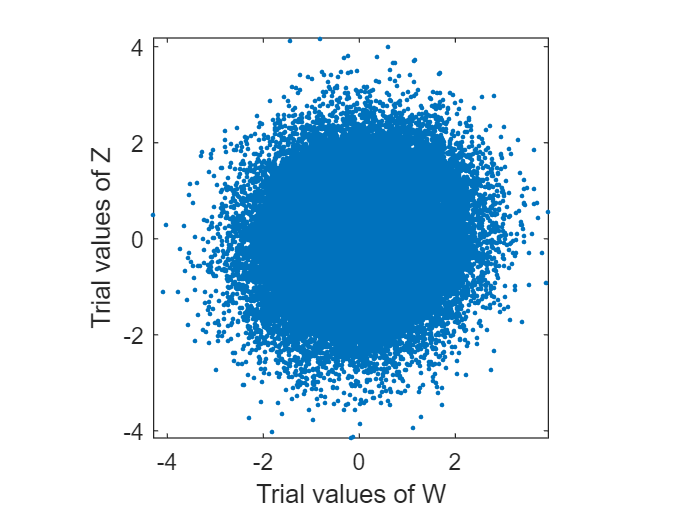

%Scatterplot
plot(W,Z,'.');
axis tight;
axis equal;
xlabel('Trial values of W');
ylabel('Trial values of Z');

## Conditional pdf

To see the dependence of one variable on another, plot histograms of one when the value of the other is fixed (in a narrow interval). Such a histogram is an estimate of the **conditional pdf, **$p_{W|Z}(w|z)$, of one variable when the other has a specific value. Adjust the angle $\theta$ above to see the effect of the correlation coefficient on how the value of $Z$ affects the distribution of the values of $W$. 

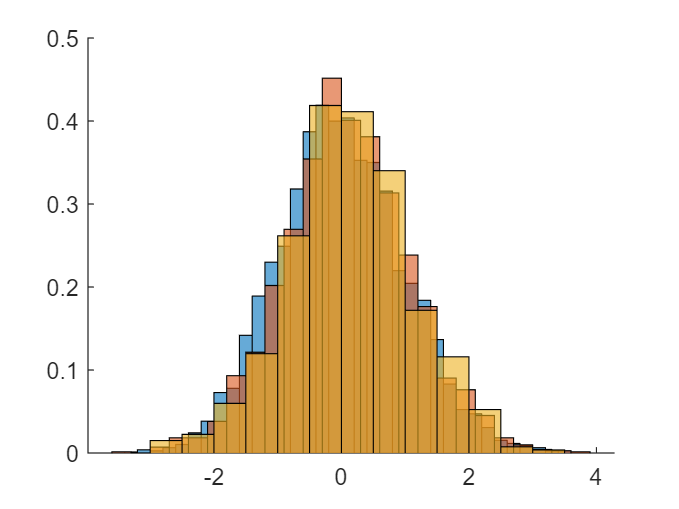

%Width of interval
wdth = 0.1;
%Z values 
zValVec = [0, 1, 2];
figure;
hold on;
for lp = 1:length(zValVec)
    zIntrv = [zValVec(lp)-wdth,zValVec(lp)+wdth];
    condWVals = W(Z>zIntrv(1) & Z<zIntrv(2));
    histogram(condWVals,'Normalization',"pdf");
end

function plotbivarcontours(rho, stdevX, stdevY, muVec)
covMatOffDiag = rho*stdevX*stdevY; 
covMat = [stdevX^2 , covMatOffDiag; covMatOffDiag, stdevY^2];
invCovMat = inv(covMat);%inverse
detCovMat = det(covMat);%determinant
xVec = linspace(-5,5,100)-muVec(1);
yVec = linspace(-5,5,100)-muVec(2);
[Xmesh, Ymesh] = meshgrid(xVec,yVec);
%matrix expression opened up
argNormExp = Xmesh.^2*invCovMat(1,1)+ Ymesh.^2*invCovMat(2,2)+...
    2*Xmesh.*Ymesh.*invCovMat(1,2);
normFac = (1/(2*pi*detCovMat^(1/2)));
pdfMesh = normFac*exp(-(1/2)*(argNormExp));
logPdfMesh = log(pdfMesh);
%Contours of log pdf
%(going from max pdf value = normalization factor, to (1/100) of max.)
figure;
contour(xVec+muVec(1),yVec+muVec(2),logPdfMesh,...
    linspace(log(normFac)-log(100),log(normFac),15));
axis tight; axis equal;
xlabel('X');
ylabel('Y');
end